# Settings

params.noSearchAgents = 30;
params.noAnten = 4;

params.logNormalMean = 0;
params.logNormalDeviation = 8.0;

params.noRealizations = 13; %200;

params.beta_t = 0.5;
params.beta_e = 1 - params.beta_t;
params.beta = [params.beta_t params.beta_e];


params.n0 = db2lin(-114 - 30);
params.B_k = 1e6;

params.p_min = 1e-8;
params.p_max = 0.25;
params.P_SBS_max = 39.81; % 46 dBm
params.P_SBS_min = 0.25*10^(-3);

params.f0 = 1e9* 8;
params.D_n = 1*420e3;
params.C_n = 1000e6;
params.kappa = 5e-27;
params.zeta = 1;

params.lamda = 1e14;
params.nu = 1e14;
params.P_tol = 1.001;

params.maxIter_woa = 300;
params.maxIter = 1500; 		%1500
% params.noSubcs = 5;
% params.noBSs   = 5;

params.Adet = 1;

params.f_local = 1e9*[0.5 0.8 1];
params.f_user = zeros(1000, 1);
for i = 1:1000
    params.f_user(i) = params.f_local(randi(length(params.f_local), 1));
end

params.gam_dl_th = 1;
params.R_th      = 2.6e7; % threshold to compute DL utility

# Network topology

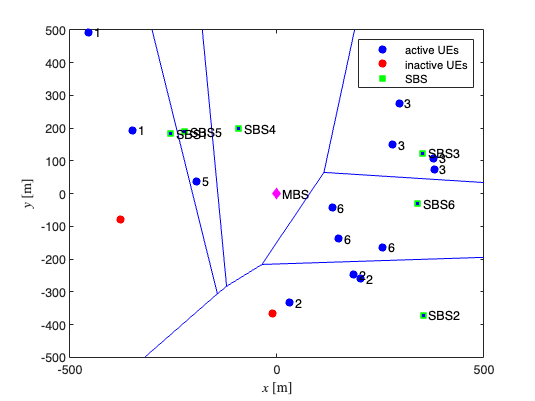

% Script to plot the system
% change noUsers and noSBS
noUsers = 13;
M_ul = 3;
M_dl = 3;
flag_plot = 1;

[UE_BS, UEs, BS] = location_voronoi(noUsers, M_ul, M_dl, flag_plot);

xlim([-500 500]);
ylim([-500 500]);


save('pos_BS_UEs.mat', 'UEs', 'BS', "UE_BS")

# Comparing the Proposed Algorithm with Exhaustive Search Methods

% compare proposed algorithm with exhaustive search in term of 
% convergence behavior and runtime

% clear all
close all

tic
load('parameter_settings.mat')

rng('default')

noSearchAgents = 30;
params.maxIter = 1500;
params.maxIter_woa = 100;

%NoUsers = 2:7; % values of N
NoUsers = 4; % 6 % to check convergence curve, we can plot the convergence curve based on the shown results on Command Window

M_ul = 2;
M_dl = 2;
noBSs   = M_ul + M_dl;
noSubcs = 3;
params.noSubcs = noSubcs;
noAnten = 4;

noRealizations = 1;

doTol = 0;

% po: percentage offloading
% su: system utility
dbstop if error

po_MECNOMA21   = zeros(length(NoUsers), noRealizations);   % 5 x noReal matrix
su_MECNOMA21   = zeros(length(NoUsers), noRealizations);   % 5 x noReal matrix
time_MECNOMA21 = zeros(length(NoUsers), noRealizations);   % 5 x noReal matrix

po_EX   = zeros(length(NoUsers), noRealizations);   % 5 x noReal matrix
su_EX   = zeros(length(NoUsers), noRealizations);   % 5 x noReal matrix
time_EX = zeros(length(NoUsers), noRealizations);   % 5 x noReal matrix

for iN = 1:length(NoUsers)

    users_no = NoUsers(iN);
    %     name = sprintf('../Conver_behave/position_data/pos_BS_UEs_%dUE.mat', users_no);
    %     load(name);

    for iReal = 1:noRealizations
        fprintf('iReal:%i/%i    iN:%i/%i',iReal,noRealizations,NoUsers(iN),NoUsers(length(NoUsers)));

        UEs.total = [2 6 10];
        while UEs.total(2) ~= floor(UEs.total(3)/2) % force N_ul = N_dl trick to get average quicker
            [UE_BS, UEs, BS] = location_voronoi(users_no, M_ul, M_dl, 0);
            % UE_BS_   == N_active x M matrix % matrix of relation of UEs and SBSs
            % UEs == 1x1 struct
            %       UEs.active   == N_active_ue x 2 matrix == (N_ul + N_dl) x 2 matrix
            %       UEs.inactive == N_inactive x 2 matrix
            %       UEs.inBS     == 1 x N_active_ue  : SBS that covers the active UEs
            %       UEs.total    == 1 x 2 matrix == [N_ul N_dl N]
            %       UEs.d        == N_active x N_active : distances between active UEs
            % BS  == 1x1 struct
            %       BS.positions == N_sbs x 2 matrix
            %       BS.SBS       == N_sbs x 1 cell : save the positions of UEs that the SBS covers
            %       BS.total = [M_ul M_dl M]
            %       BS.d     == M x M == distances between SBSs and DL SBSs
        end
        N_ul = UEs.total(1);
        sys_voronoi{iN}.UE_BS = UE_BS;
        sys_voronoi{iN}.UEs = UEs;
        sys_voronoi{iN}.BS = BS;

        [ChannelGain, ~] = channelMod(UEs, BS, noAnten, noSubcs, logNormalMean, logNormalDeviation);
        % ChannelGain == struct with
        %       hArray 	  == N x M x K cell,
        %                  each cell is a L x 1 vector  == vector of channel gain
        %                   (each SBS has L antennas)
        %       h2h       == N x N x M x K matrix
        %                   ex: h2h(1,1,m,k) = ||h_{1m}^k||^2
        %                       h2h(1,2,m,k) = |h_{1m}^k'*h_{2m}^k|
        %       h_UE      == N_ul x N_dl x K matrix
        %       G_SBS     == M_ul x M_dl x K cell
        %                       each cell == L (ul) x L (dl) matrix
        % ~     	  == N x M matrix 	== distance from UEs to SBSs


        t = randi(800, 1);
        var.f_l = params.f_user(t: t+N_ul-1);
        T_l = params.C_n ./ var.f_l;
        E_l = params.kappa .* params.C_n .*(var.f_l) .^2;

        var.eta     = params.beta_t .* params.D_n ./ (T_l);
        var.theta   = params.beta_e .* params.D_n ./ (params.zeta .* E_l);

        var.Adet = 1;

        [var.lb_woa, var.ub_woa, var.P_SBS_min, var.P_SBS_max, fobj_woa, fobj_woa_dl, fobj_bwoa] = getFunctionDetails2('SIC_MEC', UEs, BS, UE_BS, noSubcs, ChannelGain, params, var);
        %   function in ..\

        % Exhaustive search
        fprintf("\n Exhautive search \n")
        [leader_score_bwoa, leader_pos_bwoa, time] = exhaustive2(UEs, BS, UE_BS, fobj_bwoa, fobj_woa, fobj_woa_dl, ChannelGain.h2h, params, var);
        % function in ..\

        po_EX(iN, iReal) = sum(sum(leader_pos_bwoa(1:N_ul,:) ))/N_ul;
        su_EX(iN, iReal) = leader_score_bwoa;
        time_EX(iN, iReal) = time;
        leader_score_bwoa
        var.ex_lead = leader_score_bwoa;

        fprintf("BWOA \n")
        [BWOA_result, WOA_result, time] = BWOA4('WOA_SIC_MEC', doTol, UEs, BS, UE_BS, fobj_bwoa, fobj_woa, fobj_woa_dl, ChannelGain.h2h, params, var);
        % function in ..\WOA_voronoi
        po_MECNOMA21(iN, iReal) = sum(sum(BWOA_result.leader_pos(1:N_ul,:)))/users_no;
        su_MECNOMA21(iN, iReal) = BWOA_result.leader_score;
        time_MECNOMA21(iN, iReal) = time;

        BWOA.curve{iN} = BWOA_result.conver_curve;
        BWOA_result.leader_score


    end
end

iReal:1/1    iN:4/4


 Exhautive search 


exhaustive leader: 3.498279e-02
exhaustive leader: 6.643851e-01
exhaustive leader: 9.784671e-01
exhaustive leader: 1.607287e+00
exhaustive leader: 1.607287e+00
exhaustive leader: 1.628144e+00
exhaustive leader: 1.628144e+00
exhaustive leader: 1.854258e+00
exhaustive leader: 2.483077e+00
Elapsed time is 64.791679 seconds.


leader_score_bwoa = 2.4831

BWOA 


iter:3/1500, leader_score_woa:7.318273e-03, leader_score_bwoa: -1.000000e+14
Elapsed time is 0.487121 seconds.
iter:6/1500, leader_score_woa:6.736815e+00, leader_score_bwoa: -5.361560e+00
Elapsed time is 1.493936 seconds.
iter:7/1500, leader_score_woa:0, leader_score_bwoa: 6.643851e-01
Elapsed time is 3.479830 seconds.
iter:10/1500, leader_score_woa:4.934170e-03, leader_score_bwoa: 1.628201e+00
Elapsed time is 5.087854 seconds.
iter:11/1500, leader_score_woa:2.179442e-02, leader_score_bwoa: 2.482284e+00
Elapsed time is 5.798390 seconds.
Elapsed time is 5.798472 seconds.


iter = 11

ans = 2.4823

BWOA.po = mean(po_MECNOMA21, 2);
BWOA.su = mean(su_MECNOMA21, 2);
BWOA.time = mean(time_MECNOMA21, 2);

EX.po = mean(po_EX, 2);
EX.su = mean(su_EX, 2);
EX.time = mean(time_EX, 2);

% save('results\Script_compare.mat', 'BWOA', 'EX', 'NoUsers','sys_voronoi', 'noBSs', 'noSubcs');
